# Jリーグの予測モデルを構築する

clear;clc;close all;

データの読み込みと前処理

tbl_results=readtable('../../data/JLeagueResults.xlsx');
tbl_results.Category=categorical(tbl_results.Category);
tbl_results.HomeJ=categorical(tbl_results.HomeJ);
tbl_results.HomeE=categorical(tbl_results.HomeE);
tbl_results.AwayJ=categorical(tbl_results.AwayJ);
tbl_results.AwayE=categorical(tbl_results.AwayE);
summary(tbl_results)

Variables:

    MatchID: 22899×1 double

        Values:

            Min             1      
            Median          15280  
            Max             29606  
            NumMissing      1      

    Year: 22899×1 double

        Values:

            Min         1992  
            Median      2013  
            Max         2023  

    Category: 22899×1 categorical

        Values:

            ゼロックススーパーカップ                   15  
            チャンピオンシップ                        18  
            ＦＵＪＩ ＸＥＲＯＸ ＳＵＰＥＲ ＣＵＰ        13  
            ＦＵＪＩＦＩＬＭ ＳＵＰＥＲ ＣＵＰ            2  
            Ｊ１                                 5516  
            Ｊ１ サントリー                         404  
            Ｊ１ １ｓｔ                           1315  
            Ｊ１ ２ｎｄ                           1315  
            Ｊ１ ＮＩＣＯＳ                         404  
            Ｊ１・Ｊ２入替                           10  
            Ｊ１参入ＰＯ                             11  
     

2017年から2022年のリーグ戦の試合結果を使って予測モデルを構築する

J1からJ3でまとめて一つの予測モデル構築する

ind = tbl_results.Year>=2017 ...
    & tbl_results.Year<=2022 ...
    & (tbl_results.Category=='Ｊ１' ...
    | tbl_results.Category=='Ｊ２' ...
    | tbl_results.Category=='Ｊ３');
tbl_results=tbl_results(ind,:)

tbl_results = 6354×15 table
    MatchID    Year    Category       Date           KickoffTime        HomeJ       HomeE       AwayJ       AwayE      HomeGoals    AwayGoals    HomePKs    AwayPKs      Stadium      Attendance
    _______    ____    ________    __________    ___________________    ______    __________    ______    _________    _________    _________    _______    _______    ___________    __________

     19075     2017      Ｊ１      2017/02/25    2017/02/25 12:35:00    横浜FM     yokohamafm    浦和       urawa            3            2          NaN        NaN      {'日産ス'  }      39284   
     19078     2017      Ｊ１      2017/02/25    2017/02/25 14:04:00    清水       shimizu       神戸       kobe             0            1          NaN        NaN      {'アイスタ'}      17861   
     19077     2017      Ｊ１      2017/02/25    2017/02/25 14:04:00    鹿島       kashima       FC東京     ftokyo           0            1          NaN        NaN      {'カシマ'  }      28240   
     19076     2017      

teamNames=unique([tbl_results.HomeE;tbl_results.AwayE])

teamNames = 61×1 の categorical 配列
     akita 
     chiba 
     cosaka 
     cosaka_u23 
     ehime 
     ftokyo 
     ftokyo_u23 
     fujieda 
     fukuoka 
     fukushima 
     gifu 
     gosaka 
     gosaka_u23 
     hachinohe 
     hiroshima 
     imabari 
     iwaki 
     iwata 
     kagoshima 
     kanazawa 
     kashima 
     kashiwa 
     kawasakif 
     kitakyushu 
     kobe 
     kofu 
     kumamoto 
     kusatsu 
     kyoto 
     machida 


チーム名，得点を数値配列としておく(この後の高速化のため)

teamNums=zeros(size(tbl_results,1),2);
for n1=1:size(teamNames,1)
    ind_home=tbl_results.HomeE==teamNames(n1);
    ind_away=tbl_results.AwayE==teamNames(n1);
    teamNums(ind_home,1)=n1;
    teamNums(ind_away,2)=n1;
end

goalVals=[tbl_results.HomeGoals tbl_results.AwayGoals];

レーティング算出に必要な最小試合数を定める(3リーグの合計試合数)

Opt.minMatches=150;

年ごとに処理する

rateDiffs=[];
goalDiffs=[];
for yearVal=unique(tbl_results.Year)'
    % yearVal
    % categoryName
    ind = tbl_results.Year==yearVal;
    tbl_tmp=tbl_results(ind,:);
    dateVals=unique(tbl_tmp.Date);
    teamNums_tmp=teamNums(ind,:);
    goalVals_tmp=goalVals(ind,:);

    matchDates=unique(tbl_tmp.Date);

    % 予測対象日を設定
    for targetMatchDate=matchDates'
        ind = tbl_tmp.Date<targetMatchDate;
        if sum(ind)>=Opt.minMatches
            % 予測対象日までの試合数が最小試合数を超えている場合
            % レーティングを算出する
            X=zeros(sum(ind),size(teamNames,1));
            homeTeamNums=teamNums_tmp(ind,1);
            awayTeamNums=teamNums_tmp(ind,2);
            for n1=1:size(X,1)
                X(n1,homeTeamNums(n1))=1;
                X(n1,awayTeamNums(n1))=-1;
            end
            X=[X ones(sum(ind),1)];
            b=log((goalVals_tmp(ind,1)+1)./(goalVals_tmp(ind,2)+1));

            r=pinv(X)*b;

            ind_target=tbl_tmp.Date==targetMatchDate;
            rateDiffs=[rateDiffs;
                r(teamNums_tmp(ind_target,1))-r(teamNums_tmp(ind_target,2))+r(end)];
            goalDiffs=[
                goalDiffs;
                goalVals_tmp(ind_target,1)-goalVals_tmp(ind_target,2)];
        end
    end
end

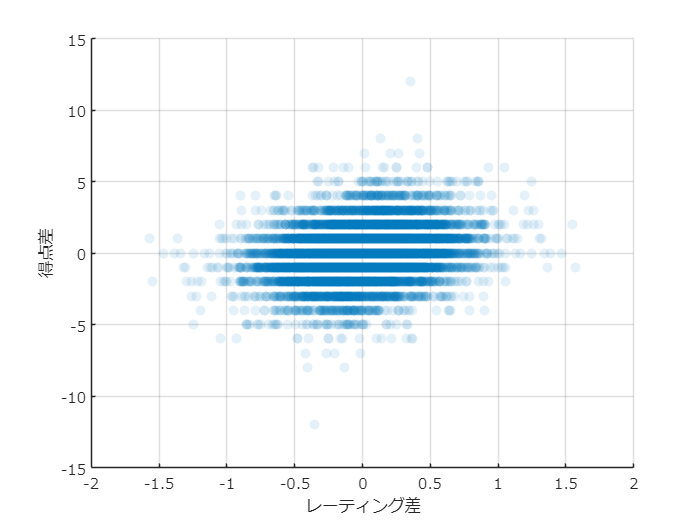

rateDiffs=[rateDiffs;-rateDiffs];
goalDiffs=[goalDiffs;-goalDiffs];

figure;hold on;grid on;
set(gca,'fontname','メイリオ')
scatter(rateDiffs, goalDiffs,'o','filled','MarkerFaceAlpha',0.1,'MarkerEdgeColor','none');
xlabel('レーティング差');ylabel('得点差');

mdl(1,:)=glmfit(rateDiffs, goalDiffs<0,"binomial");
mdl(2,:)=glmfit(rateDiffs, goalDiffs<=0,"binomial");

hold on;

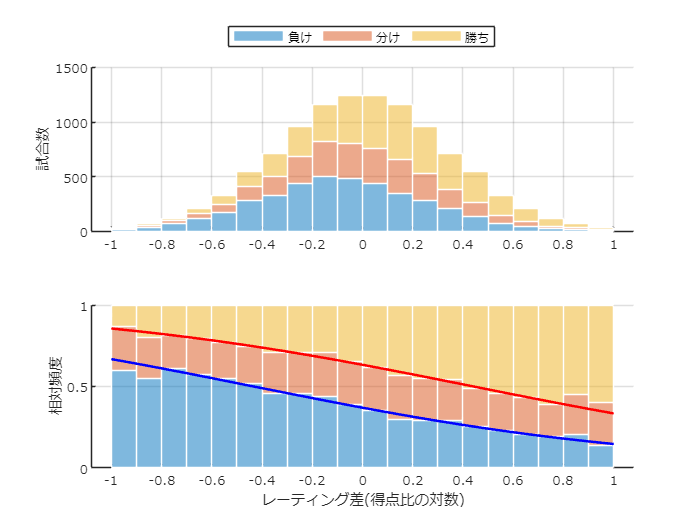

figure
tiledlayout(2,1);
nexttile;set(gca,'fontname','メイリオ');grid on;hold on;
set(gca,'fontname','メイリオ');
bins=(-1:0.1:1)*1;
hCounts=[]; %各階級の度数
ind=[];
ind=[goalDiffs<0 goalDiffs==0 goalDiffs>0];

for n1=1:size(ind,2)
    hCounts=[hCounts;histcounts(rateDiffs(ind(:,n1)),bins)];
end

bObj=bar(movmean(bins,2,'Endpoints','discard'), hCounts,'stacked', ...
    'EdgeColor','w','BarWidth',1);
ylabel('試合数');
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
legend({'負け','分け','勝ち'},'Location','northoutside','Orientation','horizontal');
ylabel('試合数');

nexttile;
set(gca,'fontname','メイリオ');grid on;hold on;
set(gca,'fontname','メイリオ');
bObj=bar(movmean(bins,2,'Endpoints','discard'), ...
    hCounts./sum(hCounts,1),'stacked', ...
    'EdgeColor','w','BarWidth',1);
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
plot(bins, glmval(mdl(1,:)',bins,'logit'),'b-','LineWidth',1.5);
plot(bins, glmval(mdl(2,:)',bins,'logit'),'r-','LineWidth',1.5);
xlabel('レーティング差(得点比の対数)');
ylabel('相対頻度');

save predictionModel_JLeague.mat
